mat=readtable("stats.csv","VariableNamingRule","preserve");
mat=mat(2:48,:);
data=table2array(mat(:,2:end));
data=data-mean(data);
data=data./std(data);

var=1/47*(data')*data;
[v,d]=eig(var,'vector');
[d,ind]=sort(d,'descend');
v=v(:,ind)

v =     0.5282   -0.0941   -0.1025    0.7599    0.3525
   -0.4237    0.4460    0.5869    0.5022   -0.1580
    0.4778    0.3178    0.5690   -0.4115    0.4215
    0.5594    0.1311    0.0718    0.0151   -0.8152
   -0.0165   -0.8210    0.5623    0.0289   -0.0932


score=data*v

score =     0.6233   -6.3123    2.2240    0.3079   -0.1548
   -1.8564   -1.3004   -1.6617    0.0603    0.3393
   -1.1309   -1.4808   -1.0434   -0.3314    0.2069
    0.8372   -0.6132   -0.8410   -1.1846    0.5036
   -0.9766   -1.1978   -1.1147   -0.6728    0.5137
   -1.3997   -0.6509   -0.7251   -0.1453    0.3836
   -0.4389   -0.8723   -0.3871   -0.2994    0.0665
    0.7008   -0.0618   -0.4566   -0.1893   -0.6097
    1.0648   -0.0194   -0.4272   -0.5625   -1.2719
    0.2218    0.1345   -0.0548   -0.4257   -0.1491


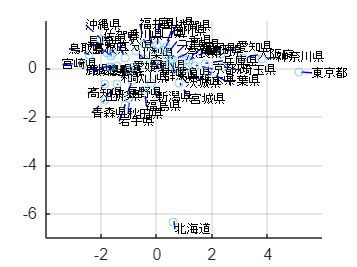


plotData=score(:,1:2);
plotText=mat{:,1};
textPosition=calcTextPosInScatterPlot(plotData);
figure
hold on;
for n1=1:size(plotData,1)
    plot([textPosition(n1,1) plotData(n1,1)],[textPosition(n1,2) plotData(n1,2)],'b--')
    text(textPosition(n1,1), textPosition(n1,2), plotText(n1,:), 1);
end
scatter(plotData(:,1),plotData(:,2));
grid on;
set(gca,'FontName','arial','FontSize',12)

hold off;

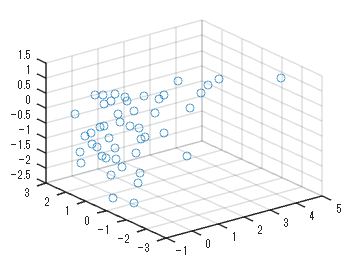

scatter3(data(:,1),data(:,2),data(:,3));


cumsum(d)*100/sum(d)

ans =    54.8180
   79.8118
   89.6226
   96.4436
  100.0000
